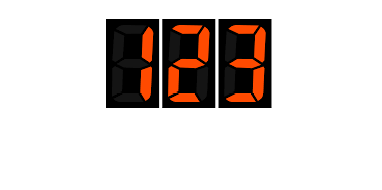

% Load image
[A,c] = imread('numbers.png');
A = A(1:90, 1:168);
imshow(A,c)

figure
[n,m] = size(A);

% Define labels
L = [1, 2, 3]; % 1 - white, 2 - black, 3 - red
% Define seeds
S = [35, 37, 3; 81, 41, 3; 77, 64, 3; 30, 103, 3; 51, 150, 3; 83, 125, 3; 79, 123, 3; 56, 63, 3; 15, 104, 3;
    20, 47, 1; 72, 45, 1; 69, 64, 1; 68, 113, 1; 13, 113, 1; 73, 166, 1; 42, 159, 1; 15, 92, 1; 76, 68, 1;
    72, 66, 2; 15, 40, 2; 51, 157, 2; 48, 150, 2; 49, 91, 2; 53, 46, 2; 30, 47, 2; 77, 90, 2; 48, 151, 2];
T = 5000; % Number of steps
LD = zeros(n,m, numel(L));  % initalize limiting distribution
img = zeros(n,m,3);
for p = 1:3
    for i = 1:n
        for j = 1:m
            img(i,j,p) = c(A(i,j)+1,p);
        end
    end
end

tic
W = sparse(calculate_weights(img,150));
toc

Elapsed time is 1.233982 seconds.


tic
H = construct_hamiltonian(W, 0.001);
toc

Elapsed time is 1.790491 seconds.


for i = 1:numel(L) % use parfor if available
    sprintf("Working with label: %d", i)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(numel(A),1);
    for p = 1:subset_length
        A_sub(subset(p,2) + m*(subset(p,1)-1)) = 1; %A(subset(p,1), subset(p,2));
    end
    state = 1/sqrt(subset_length) * sparse(A_sub);
    D = zeros(n*m,T);
    for t = 1:T
        state = update_state(-1i, H, state);
        D(:,t) = retrieve_position(state);
    end
    LD(:,:,i) = reshape(1/T * sum(D,2),n,m);
    sprintf("Limiting distribution of label %d found", i)
end

ans = "Working with label: 1"

ans = "Limiting distribution of label 1 found"

ans = "Working with label: 2"

ans = "Limiting distribution of label 2 found"

ans = "Working with label: 3"

ans = "Limiting distribution of label 3 found"

B = zeros(n,m);
b = [4,3,2];
figure
for i = 1:n
    for j = 1:m
        k = find_seed(LD,i,j);
        B(i,j) = k;
    end
end

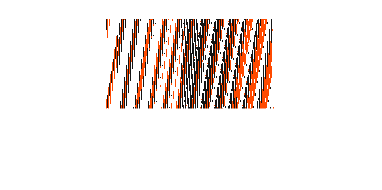

figure
imshow(B,c(b,:))